# Create and Customize Bar Graphs

Vertical bar graphs present data with rectangular bars with heights proportional to the values that they represent.

### Read Temperature Data

We will use `'BostonTemp.mat' `to demonstrate how to create and customize vertical bar graphs. The MAT-file contains monthly temperature data of Boston, MA (Logan Airport) by the U.S. National Oceanic and Atmospheric Administration between 2000 and 2020.

load BostonTemp.mat

### Basic Bar Graph

Visualize the monthly temperature for one of the years between 2000 and 2020.

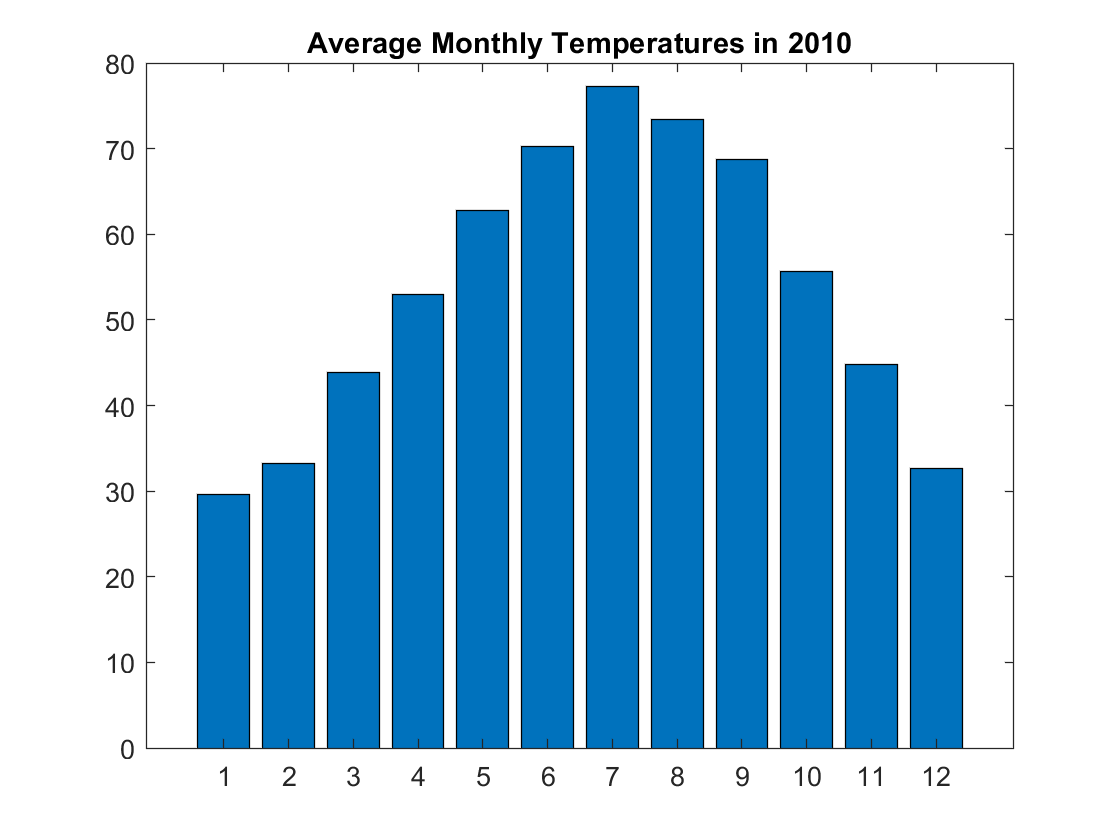

yearIdx = 11;      % Choose a year
bar(1:12,Temperatures(yearIdx,:));
title(sprintf("Average Monthly Temperatures in %d",Year(yearIdx)))

## Customization

### Customize Bar Appearance

A bar graph can be customized to have user-specified bar width, color and transparency.

Use the third argument to `bar` to modify the bar width. Modify the *FaceColor* and *FaceAlpha *properties using Name, Value pairs.

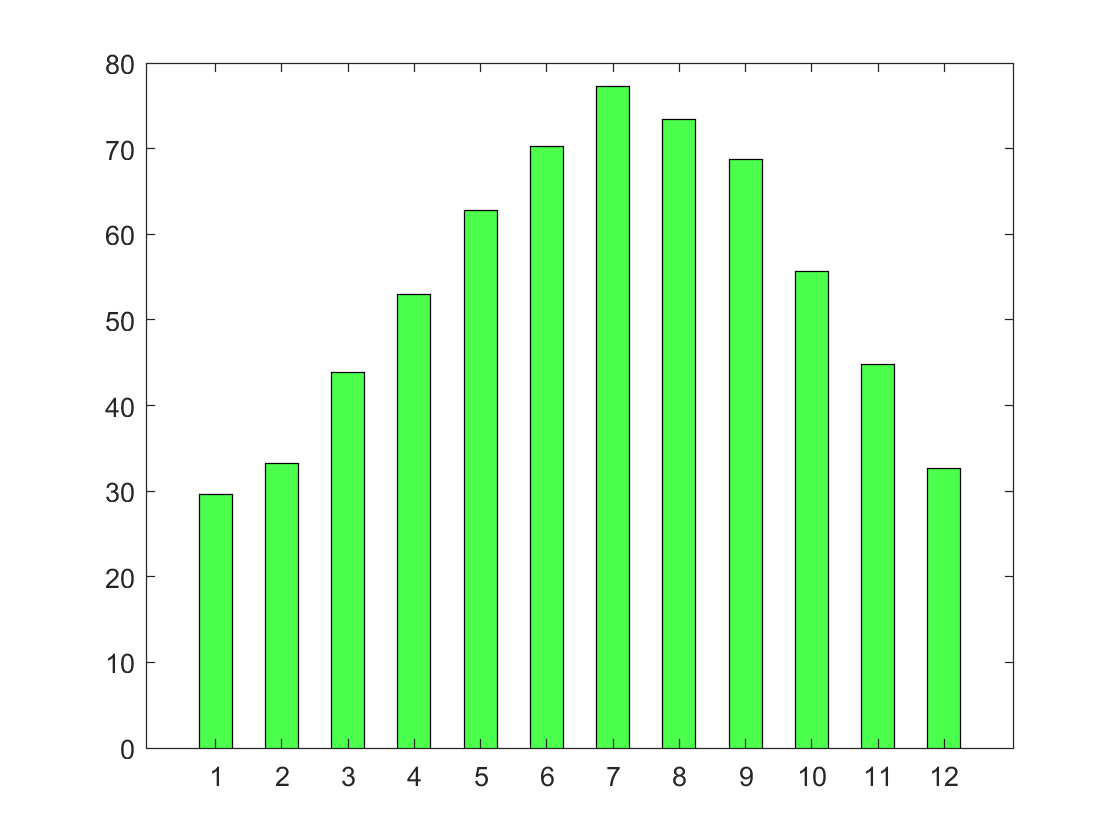

barColor = "green";
barTransparency = 0.7;
barWidth = 0.5;

figure
b = bar(1:12,Temperatures(yearIdx,:),barWidth,...  % Specify bar width in the third argument
    "FaceColor",barColor, ...                      % Specify bar color
    "FaceAlpha",barTransparency);                  % Specify bar transparency between 0.1 and 1.0

### Add Datatip Labels and Custom Axis Ticks

Add data labels by accessing bar end points through the *XEndPoints* and *YEndPoints* properties of the Bar object. Improve graph by adding padding to the axes and adding custom labels to the x-axis.

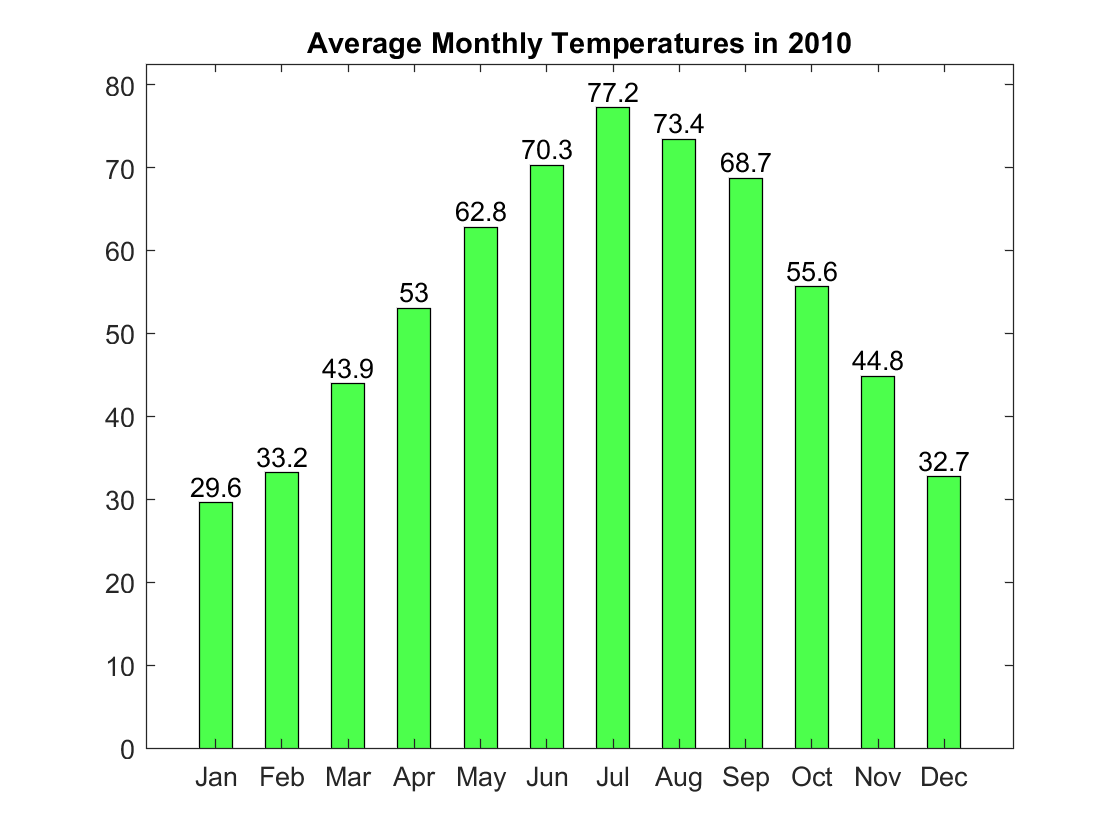

xtips = b.XEndPoints; 
ytips = b.YEndPoints;
labels = string(b.YData);
text(xtips,ytips,labels,...
    "HorizontalAlignment","center",... % Align the text labels
    "VerticalAlignment","bottom");

axis padded % Add padding to the axes to account for datatip labels
xticklabels(Months)
title(sprintf("Average Monthly Temperatures in %d",Year(yearIdx)))

### Group Bar Graphs and Customize Individual Bar Colors

Grouped bar graphs can be used to compare measured values for different discrete categories or cases using two or more color-coded bars for each category or case. 

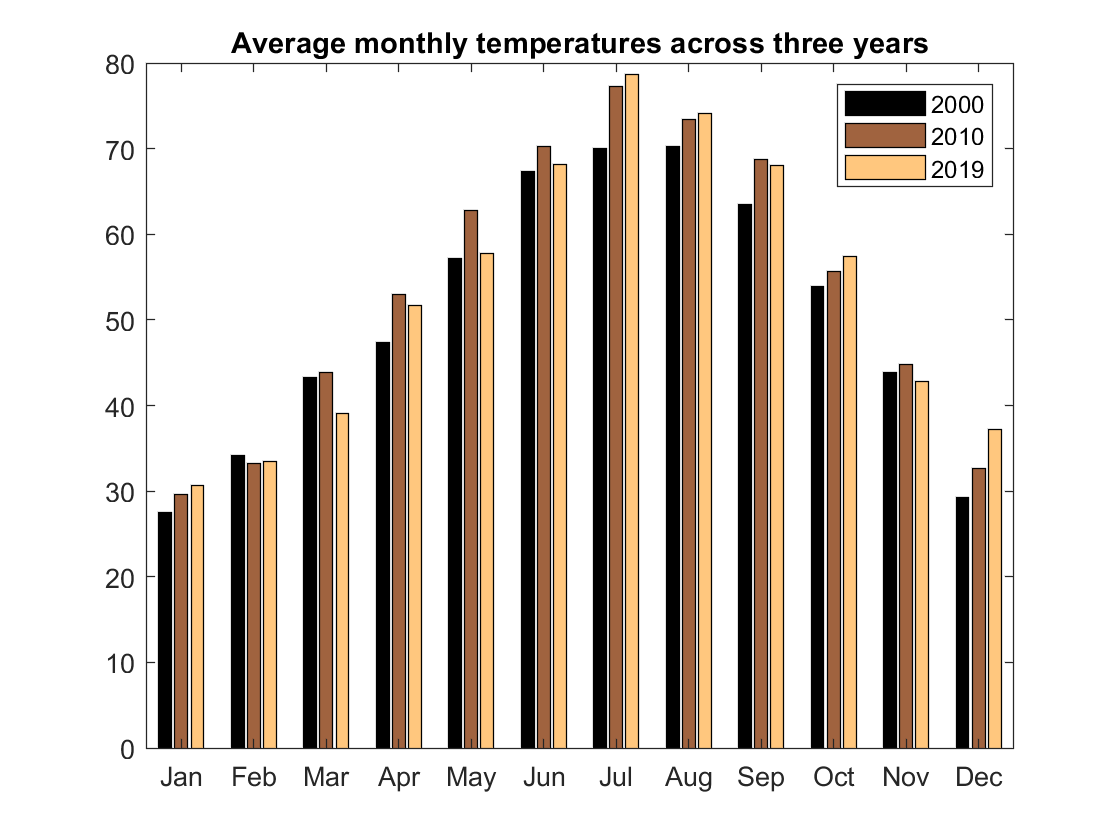

yearIdx1 = 1;  % Choose three different years to compare the average monthly temperatures
yearIdx2 = 11;
yearIdx3 = 20;
TempGroup = [Temperatures(yearIdx1,:);Temperatures(yearIdx2,:);...
    Temperatures(yearIdx3,:)];

figure
b1 = bar(1:12,TempGroup,...
    "FaceColor","flat");           % Set FaceColor to flat to use colormaps
colormap copper        % Choose a colormap
for k = 1:3
    b1(k).CData = k;               % Set the color from the colormap for each set of bars using the CData property
end

legend(sprintf("%d",Year(yearIdx1)),sprintf("%d",Year(yearIdx2)),sprintf("%d",Year(yearIdx3)))
title("Average monthly temperatures across three years");
xticklabels(Months)

### Overlay Bar Graphs and Customize Bar Edges

Overlayed bar graphs can provide a compelling visualization of two sets of data with similar x-values. Compare the mean temperature across all years with the temperatures from 2010.

Modify the *EdgeColor* and *LineWidth *properties using Name, Value pairs. Specify a legend and axes labels to complete the graph.

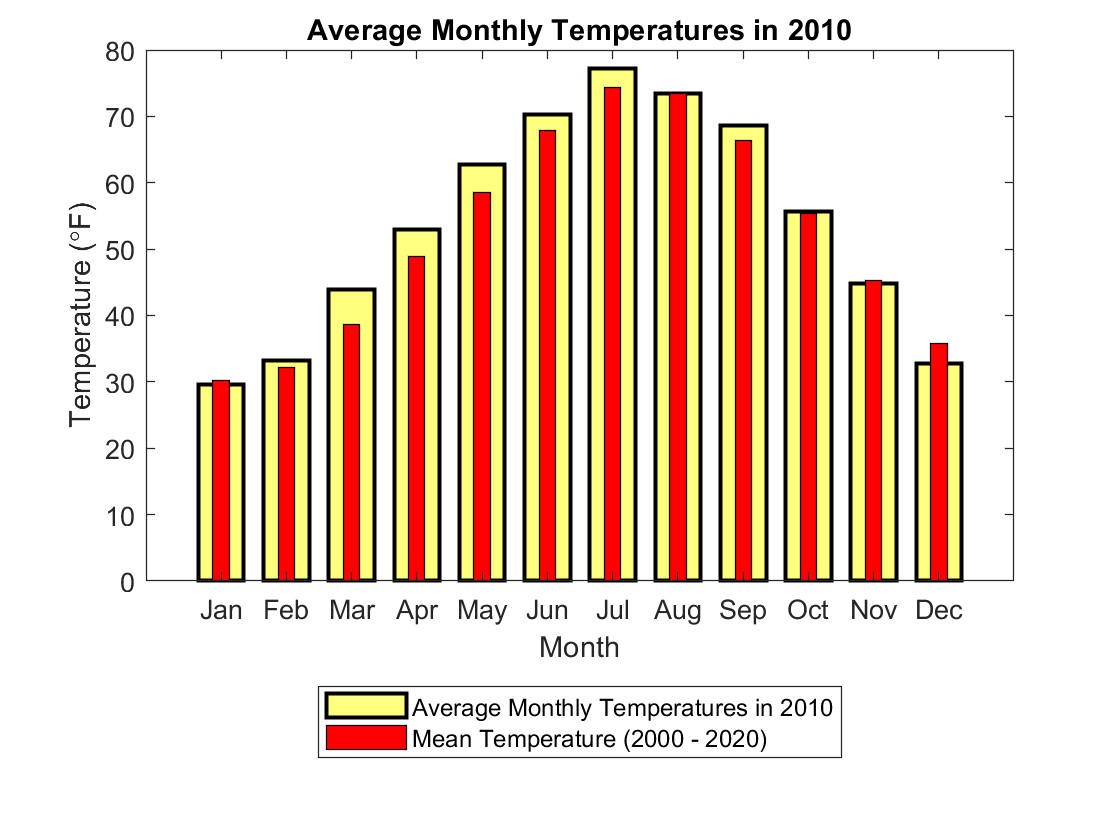

b2 = bar(1:12,Temperatures(yearIdx,:),0.7,... 
    "FaceColor","yellow", ...                 
    "FaceAlpha",0.5,...                       
    "EdgeColor","black",...                   % Specify the edge color as black
    "LineWidth",1.5);                         % Specify the edge line width

hold on
b3 = bar(1:12,mean(Temperatures),0.25,...
    "FaceColor","red");

legend(sprintf("Average Monthly Temperatures in %d",Year(yearIdx)),...
    "Mean Temperature (2000 - 2020)",...
    "Location","southoutside")
title(sprintf("Average Monthly Temperatures in %d",Year(yearIdx)))
xticklabels(Months)
xlabel("Month")
ylabel("Temperature (\circF)")

## **Additional Information**

### **Get All Bar Properties**

Graphics objects in MATLAB have many properties. To see all the properties of a Bar, uncomment the following code. View or modify these properties using dot notation.

% get(b)

### Documentation

Follow the link below to go to the documentation page to learn about the plot type in detail.

[Vertical Bar Graph](https://www.mathworks.com/help/matlab/ref/bar.html?searchHighlight=bar&s_tid=srchtitle)

Copyright (c) 2021, The MathWorks, Inc.